# Passive High-Pass Filters – Theory, Circuit Analysis, and Response Characteristics

**MATLAB Tutorial for Undergraduate Engineering Students**

Based on: Chapter 15 - Active Filters (Floyd's Electronic Devices)

Author: Kessad Mohamed Dhia Eddine

Github: DhiaKessad

Objective: This comprehensive tutorial covers passive high-pass filter theory, including RC, RL, and RLC configurations, frequency response characteristics (Butterworth, Chebyshev, Bessel), time-domain behavior, and MATLAB modeling.

## 1. Introduction to High-Pass Filter Theory

**What is a High-Pass Filter?**

A high-pass filter (HPF) is one that significantly attenuates or rejects all frequencies below the critical frequency (fc) and passes all frequencies above fc. High-pass filters are the complement of low-pass filters.

**Key Characteristics from Floyd's Textbook:**

- **Passband:** All frequencies above the critical frequency fc

- **Stopband:** All frequencies below fc are attenuated

- **Critical Frequency (fc):** The frequency at which the output is 70.7% (−3 dB) of the passband response

- **Transition Region:** The region between stopband and passband

- **Roll-off Rate:** The rate at which attenuation increases below fc, measured in dB/decade

**Practical Applications:**

- AC coupling: Blocking DC while passing AC signals

- Audio systems: Removing low-frequency rumble and hum

- Communication systems: Eliminating low-frequency interference

- Instrumentation: Removing DC offset from measurements

- Crossover networks: Directing high frequencies to tweeters

- Differentiation circuits: Emphasizing rapid signal changes

## 2. High-Pass Filter Fundamentals

**Ideal vs. Actual Response**

According to Floyd (Figure 15-2):

- **Ideal Response:** Instantaneous transition at fc with complete rejection below fc (brick-wall characteristic) - not achievable in practice

- **Actual Response:** Gradual transition with roll-off rate determined by filter order (number of poles)

**High-Frequency Limitations:**

The high-frequency passband of practical circuits is limited by:

- Finite bandwidth of active components

- Parasitic capacitances in circuit components

- Stray capacitances in wiring and layout

- Skin effect in conductors at very high frequencies

**Roll-off Rates by Filter Order:**

- First-order (1-pole): -20 dB/decade below fc

- Second-order (2-pole): -40 dB/decade below fc

- Third-order (3-pole): -60 dB/decade below fc

- nth-order (n-pole): -20n dB/decade below fc

Note: The roll-off occurs BELOW fc for high-pass filters (opposite of low-pass)

## 3. RC High-Pass Filter (Single-Pole)

**Circuit Configuration**

The RC high-pass filter is created by swapping the resistor and capacitor positions from the low-pass configuration:

- A capacitor (C) in series with the input

- A resistor (R) connected from output to ground

- Output voltage measured across the resistor

Circuit Topology:

**Key Principle:** At low frequencies, the capacitor has high impedance (acts as an open circuit), blocking the signal. At high frequencies, the capacitor has low impedance (acts as a short circuit), allowing the signal to pass.

**Mathematical Derivation**

Using voltage divider with impedances in s-domain:

Impedances:


$$Z_C = \frac{1}{sC}$$



$$Z_R = R$$


Transfer function using voltage divider (output across R):


$$H(s) = \frac{Z_R}{Z_C + Z_R} = \frac{R}{\frac{1}{sC} + R}$$


Multiplying numerator and denominator by sC:


$$H(s) = \frac{sRC}{1 + sRC} = \frac{sRC}{1 + sRC}$$


Standard form (factor out time constant):


$$H(s) = \frac{s}{s + \frac{1}{RC}}$$


Alternative form showing zero at origin:


$$H(s) = \frac{sRC}{1 + sRC}$$


**Critical Frequency Derivation**

The critical frequency occurs when the capacitive reactance equals resistance:


$$X_C = R$$



$$\frac{1}{2\pi f_c C} = R$$


Solving for fc (same formula as low-pass):


$$f_c = \frac{1}{2\pi RC}$$


At the critical frequency:

- Output voltage is 70.7% of passband value (-3 dB)

- Phase shift is +45° (leading)

- Capacitive reactance equals resistance

## 4. MATLAB Implementation - RC High-Pass Filter

Define component values

% RC High-Pass Filter Parameters
R_rc = 10e3;             % Resistance = 10 kΩ
C_rc = 1e-6;             % Capacitance = 1 μF

% Calculate critical frequency
fc_rc = 1 / (2 * pi * R_rc * C_rc);
wc_rc = 2 * pi * fc_rc;
tau_rc = R_rc * C_rc;

% Display parameters
fprintf('RC HIGH-PASS FILTER PARAMETERS:\n');

RC HIGH-PASS FILTER PARAMETERS:


fprintf('=================================\n');

fprintf('Resistance R = %.2f kΩ\n', R_rc/1e3);

Resistance R = 10.00 kΩ


fprintf('Capacitance C = %.2f μF\n', C_rc/1e6);

Capacitance C = 0.00 μF


fprintf('Critical frequency fc = %.2f Hz\n', fc_rc);

Critical frequency fc = 15.92 Hz


fprintf('Time constant τ = %.2f ms\n', tau_rc/1e-3);

Time constant τ = 10.00 ms


fprintf('Roll-off rate: -20 dB/decade below fc (single-pole)\n\n');

Roll-off rate: -20 dB/decade below fc (single-pole)




% Create transfer function (high-pass)
s = tf('s');
H_rc_hp = (s*R_rc*C_rc) / (1 + s*R_rc*C_rc);

fprintf('Transfer Function H(s):\n');

Transfer Function H(s):


disp(H_rc_hp);

  tf with properties:

       Numerator: {[0.0100 0]}
     Denominator: {[0.0100 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Display pole and zero locations
poles_rc = pole(H_rc_hp);
zeros_rc = zero(H_rc_hp);
fprintf('Pole location: s = %.2f rad/s\n', poles_rc);

Pole location: s = -100.00 rad/s


fprintf('Zero location: s = %.2f rad/s (at origin)\n\n', zeros_rc);

Zero location: s = 0.00 rad/s (at origin)



## 5. Frequency Response Analysis - RC High-Pass Filter

Generate frequency vector (logarithmic spacing)

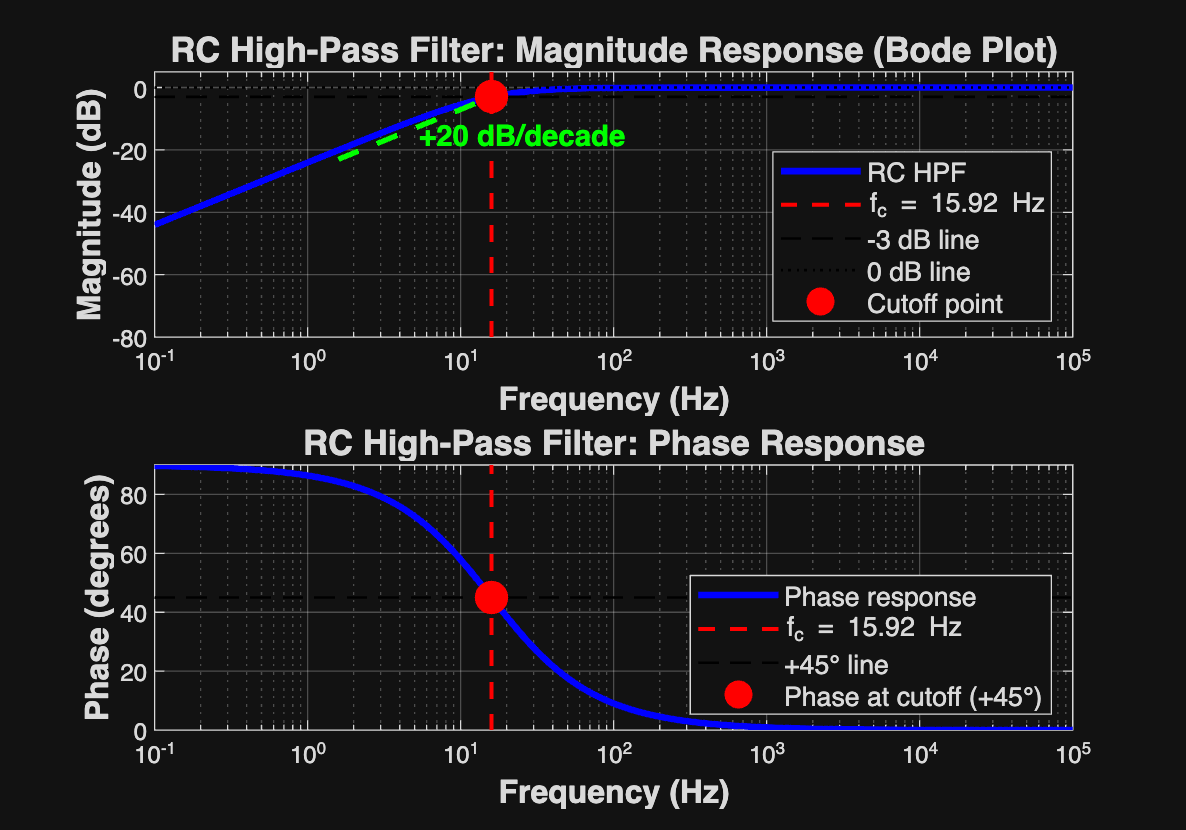

f = logspace(-1, 5, 2000);    % 0.1 Hz to 100 kHz
w = 2 * pi * f;

% Compute frequency response
[mag_rc, phase_rc] = bode(H_rc_hp, w);
mag_rc = squeeze(mag_rc);
phase_rc = squeeze(phase_rc);
mag_dB_rc = 20 * log10(mag_rc);

% Create comprehensive Bode plot
figure('Position', [100, 100, 1000, 700]);

% Magnitude plot
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc_rc, fc_rc], [-80, 5], 'r--', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
semilogx([f(1), f(end)], [0, 0], 'k:', 'LineWidth', 1);
plot(fc_rc, -3, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');

% Add roll-off rate annotation
f_decade_low = fc_rc / 10;
semilogx([f_decade_low, fc_rc], [-23, -3], 'g--', 'LineWidth', 2);
text(fc_rc/3, -15, '+20 dB/decade', 'FontSize', 11, 'Color', 'g', 'FontWeight', 'bold');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC High-Pass Filter: Magnitude Response (Bode Plot)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC HPF', sprintf('f_c = %.2f Hz', fc_rc), '-3 dB line', '0 dB line', ...
       'Cutoff point', 'Location', 'southeast', 'FontSize', 10);
ylim([-80, 5]);
xlim([f(1), f(end)]);

% Phase plot
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc_rc, fc_rc], [0, 90], 'r--', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [45, 45], 'k--', 'LineWidth', 1);
plot(fc_rc, 45, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC High-Pass Filter: Phase Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('Phase response', sprintf('f_c = %.2f Hz', fc_rc), ...
       '+45° line', 'Phase at cutoff (+45°)', 'Location', 'southeast', 'FontSize', 10);
ylim([0, 90]);
xlim([f(1), f(end)]);

## Analysis of RC High-Pass Filter Response

**Frequency Domain Observations:**

- **Stopband (f**** << fc):** Gain decreases at +20 dB/decade going toward DC, phase approaches +90°

- **Critical frequency (f = fc):** Gain = -3 dB, phase = +45°

- **Passband (f >> fc):** Gain approaches 0 dB (unity gain), phase approaches 0°

**Key Attenuation Points:**

- At fc/10: Gain ≈ -20 dB (10% of passband amplitude)

- At fc/100: Gain ≈ -40 dB (1% of passband amplitude)

- At DC (f = 0): Gain → -∞ dB (complete attenuation)

**Phase Characteristics:**

- At DC: Phase = +90° (capacitor dominates, leading behavior)

- At fc: Phase = +45° (equal resistive and reactive components)

- At high frequencies: Phase → 0° (resistor dominates)

The +20 dB/decade roll-off below fc is characteristic of first-order systems. Note: The phase is POSITIVE (leading) unlike low-pass filters (lagging).

## 6. Time-Domain Response - RC High-Pass Filter

**Step Response Analysis**

The high-pass filter's step response demonstrates its AC coupling behavior. The output cannot sustain a DC level and will decay back to zero.

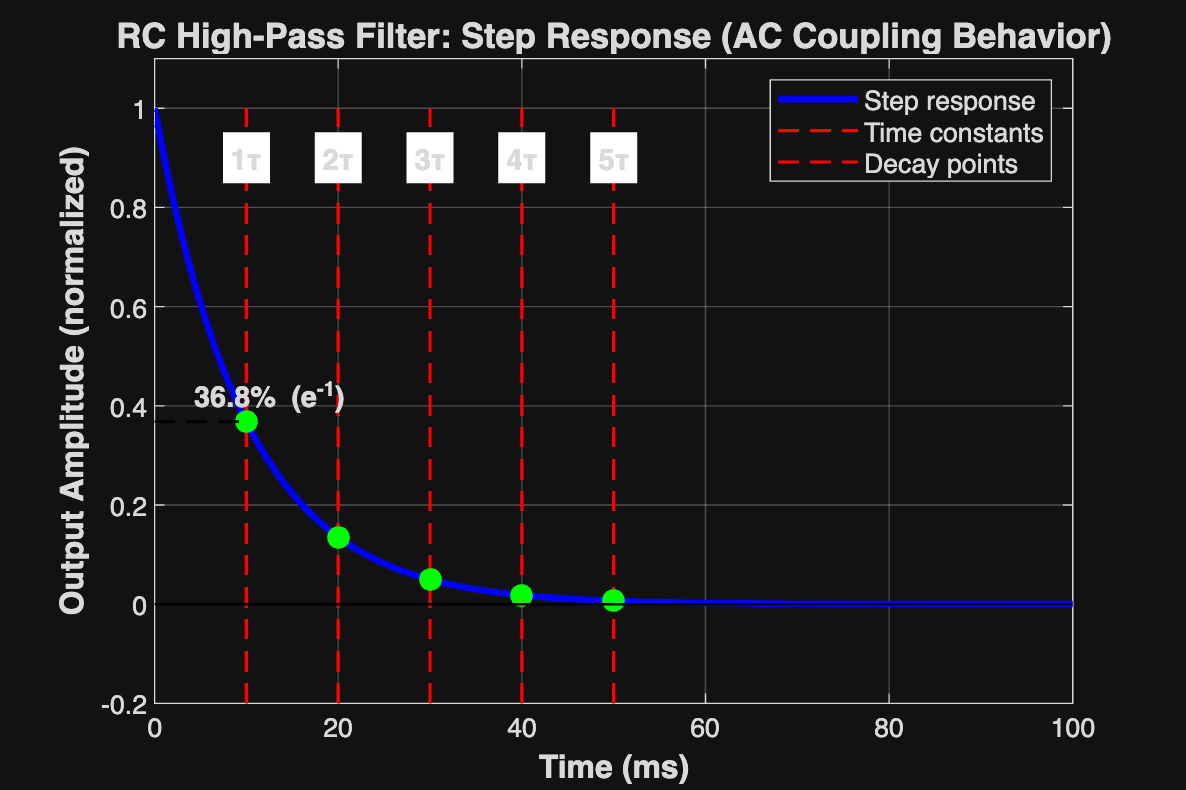

% Time vector for step response
t_step = linspace(0, 10*tau_rc, 2000);

% Compute step response
[y_step_rc, t_out_rc] = step(H_rc_hp, t_step);

% Create step response plot
figure('Position', [100, 100, 900, 600]);
plot(t_out_rc*1e3, y_step_rc, 'b-', 'LineWidth', 2.5);
hold on;

% Mark time constants
for n = 1:5
    plot([n*tau_rc*1e3, n*tau_rc*1e3], [-0.2, 1], 'r--', 'LineWidth', 1.2);
    text(n*tau_rc*1e3, 0.9, sprintf('%dτ', n), 'FontSize', 11, ...
         'HorizontalAlignment', 'center', 'BackgroundColor', 'white', 'FontWeight', 'bold');
end

% Mark key decay points
decay_percentages = [0.368, 0.135, 0.050, 0.018, 0.007];  % e^(-t/τ) values
time_constants = [1, 2, 3, 4, 5];
for i = 1:length(decay_percentages)
    plot(time_constants(i)*tau_rc*1e3, decay_percentages(i), 'go', ...
         'MarkerSize', 8, 'MarkerFaceColor', 'g');
end

% Highlight 36.8% decay point
plot([0, tau_rc*1e3], [0.368, 0.368], 'k--', 'LineWidth', 1);
text(tau_rc*1e3*0.4, 0.42, '36.8% (e^{-1})', 'FontSize', 11, 'FontWeight', 'bold');

% Add zero line
plot([0, max(t_step)*1e3], [0, 0], 'k-', 'LineWidth', 1);

hold off;
grid on;
xlabel('Time (ms)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Output Amplitude (normalized)', 'FontSize', 12, 'FontWeight', 'bold');
title('RC High-Pass Filter: Step Response (AC Coupling Behavior)', 'FontSize', 13, 'FontWeight', 'bold');
legend('Step response', 'Time constants', 'Decay points', 'Location', 'northeast', 'FontSize', 10);
xlim([0, 10*tau_rc*1e3]);
ylim([-0.2, 1.1]);

## Time-Domain Characteristics

**Exponential Decay Equation:**

For a step input, the high-pass filter output is:


$$V_{out}(t) = V_{in} \cdot e^{-t/\tau}$$


where τ = RC is the time constant.

**Key Time Response Points:**

- At t = 0⁺: Output jumps to 100% (differentiator action)

- At t = τ: Output decays to 36.8% (1/e) of initial value

- At t = 2τ: Output decays to 13.5% of initial value

- At t = 3τ: Output decays to 5.0% of initial value

- At t = 5τ: Output decays to 0.7% of initial value (essentially zero)

**Physical Interpretation:**

- **Initial response:** Capacitor acts as short circuit, full signal passes

- **DC blocking:** Capacitor charges up, blocking DC component

- **Exponential decay:** Output returns to zero (cannot pass DC)

- **AC coupling:** Only changes (AC components) are passed

- **Differentiation:** Emphasizes rapid changes in input signal

For our circuit: τ = 10 ms, meaning DC is blocked and only AC above ~16 Hz passes. This is ideal for audio AC coupling applications.

## 7. Pulse Response - Demonstrating AC Coupling

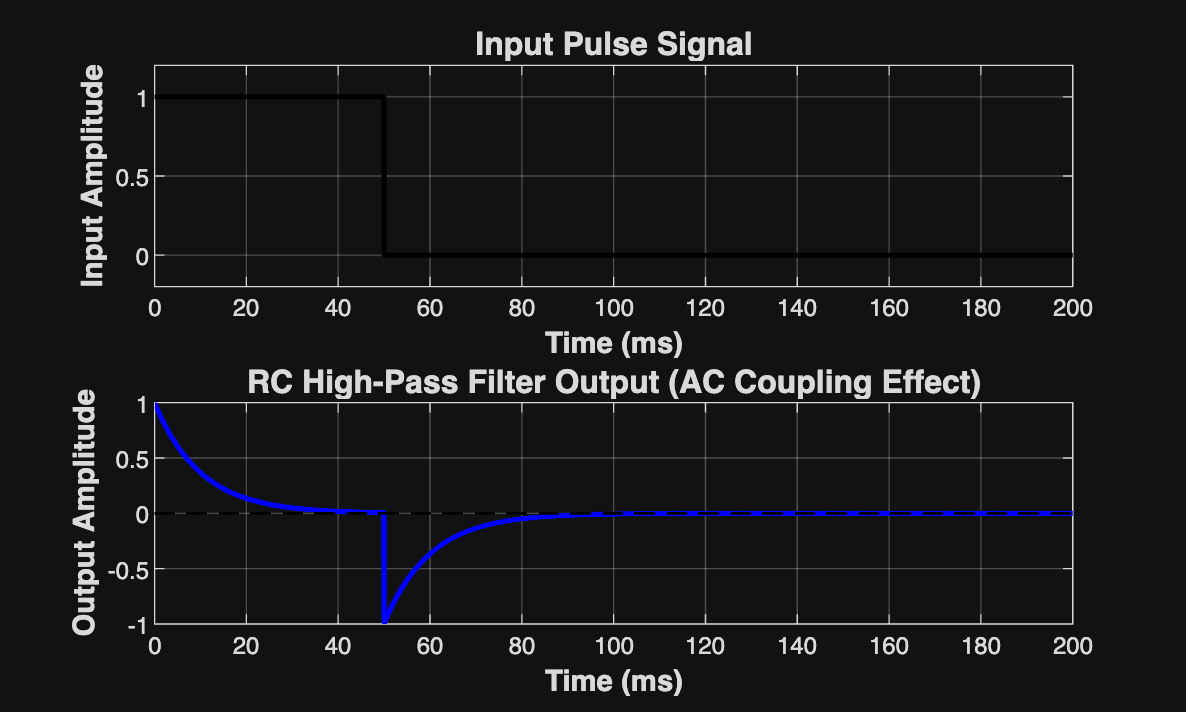

% Create pulse input signal
t_pulse = linspace(0, 20*tau_rc, 4000);
pulse_width = 5*tau_rc;
pulse_input = double(t_pulse < pulse_width);  % Pulse from 0 to 5τ

% Simulate response to pulse
[y_pulse, t_pulse_out] = lsim(H_rc_hp, pulse_input, t_pulse);

% Plot pulse response
figure('Position', [100, 100, 1000, 600]);

subplot(2, 1, 1);
plot(t_pulse*1e3, pulse_input, 'k-', 'LineWidth', 2);
grid on;
xlabel('Time (ms)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Input Amplitude', 'FontSize', 11, 'FontWeight', 'bold');
title('Input Pulse Signal', 'FontSize', 12, 'FontWeight', 'bold');
ylim([-0.2, 1.2]);
xlim([0, 20*tau_rc*1e3]);

subplot(2, 1, 2);
plot(t_pulse_out*1e3, y_pulse, 'b-', 'LineWidth', 2);
hold on;
plot([0, 20*tau_rc*1e3], [0, 0], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Time (ms)', 'FontSize', 11, 'FontWeight', 'bold');
ylabel('Output Amplitude', 'FontSize', 11, 'FontWeight', 'bold');
title('RC High-Pass Filter Output (AC Coupling Effect)', 'FontSize', 12, 'FontWeight', 'bold');
xlim([0, 20*tau_rc*1e3]);

## Pulse Response Analysis

**Observations:**

- **Rising edge:** Sharp positive spike (differentiator action on rapid change)

- **Flat portion:** Output decays exponentially toward zero (DC component blocked)

- **Falling edge:** Sharp negative spike (differentiator action on negative change)

- **Average value:** Always returns to zero (AC coupling - no DC component)

This behavior demonstrates why high-pass filters are called "AC coupling" circuits: they remove the DC component while passing AC (changing) signals.

## 8. RL High-Pass Filter

**Circuit Configuration**

An RL high-pass filter uses an inductor instead of a capacitor:

- An inductor (L) in series with the input

- A resistor (R) to ground

- Output voltage measured across the inductor

Circuit Topology:

Note: For high-pass, output is across L (not R)

**Key Principle:** At low frequencies, the inductor has low impedance, dropping little voltage. At high frequencies, the inductor has high impedance, passing most of the signal voltage.

**Transfer Function Derivation**

Impedances in s-domain:


$$Z_L = sL$$



$$Z_R = R$$


Using voltage divider (output across L):


$$H(s) = \frac{Z_L}{Z_L + Z_R} = \frac{sL}{sL + R}$$


Standard form:


$$H(s) = \frac{s}{s + \frac{R}{L}}$$


Alternative form:


$$H(s) = \frac{s\frac{L}{R}}{1 + s\frac{L}{R}}$$


**Critical Frequency**

Occurs when inductive reactance equals resistance:


$$X_L = R$$



$$2\pi f_c L = R$$



$$f_c = \frac{R}{2\pi L}$$


**Time Constant**


$$\tau_{RL} = \frac{L}{R}$$


## 9. MATLAB Implementation - RL High-Pass Filter

% RL High-Pass Filter Parameters
R_rl = 1e3;              % Resistance = 1 kΩ
L_rl = 10;               % Inductance = 10 H (chosen for same fc as RC)

% Calculate critical frequency
fc_rl = R_rl / (2 * pi * L_rl);
tau_rl = L_rl / R_rl;

fprintf('RL HIGH-PASS FILTER PARAMETERS:\n');

RL HIGH-PASS FILTER PARAMETERS:


fprintf('=================================\n');

fprintf('Resistance R = %.2f kΩ\n', R_rl/1e3);

Resistance R = 1.00 kΩ


fprintf('Inductance L = %.2f H\n', L_rl);

Inductance L = 10.00 H


fprintf('Critical frequency fc = %.2f Hz\n', fc_rl);

Critical frequency fc = 15.92 Hz


fprintf('Time constant τ = %.2f ms\n', tau_rl/1e-3);

Time constant τ = 10.00 ms


fprintf('Roll-off rate: -20 dB/decade below fc (single-pole)\n\n');

Roll-off rate: -20 dB/decade below fc (single-pole)




% Create transfer function (high-pass RL)
H_rl_hp = s / (s + R_rl/L_rl);

fprintf('RL Transfer Function H(s):\n');

RL Transfer Function H(s):


disp(H_rl_hp);

  tf with properties:

       Numerator: {[1 0]}
     Denominator: {[1 100]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 10. Frequency Response Comparison - RC vs RL High-Pass

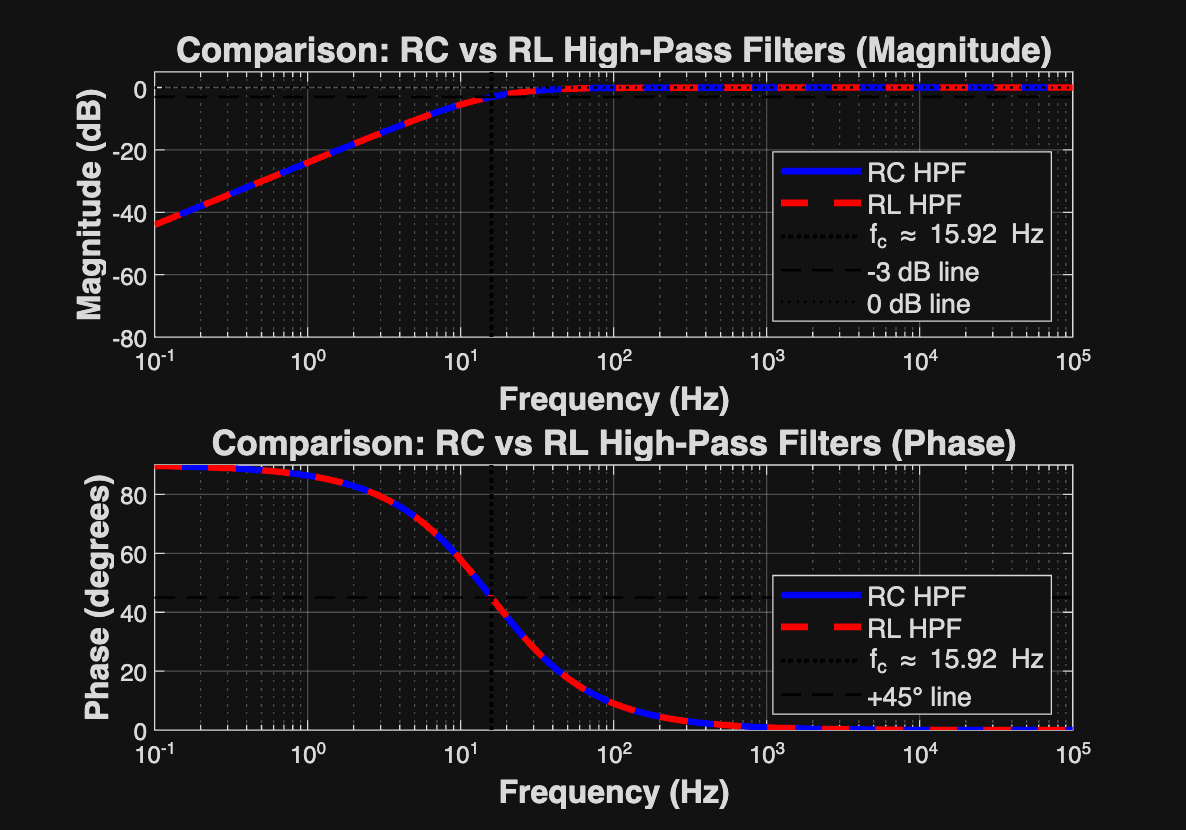

% Compute frequency response for RL high-pass filter
[mag_rl, phase_rl] = bode(H_rl_hp, w);
mag_rl = squeeze(mag_rl);
phase_rl = squeeze(phase_rl);
mag_dB_rl = 20 * log10(mag_rl);

% Compare RC and RL high-pass filters
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_dB_rl, 'r--', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-80, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
semilogx([f(1), f(end)], [0, 0], 'k:', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL High-Pass Filters (Magnitude)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC HPF', 'RL HPF', sprintf('f_c ≈ %.2f Hz', fc_rc), ...
       '-3 dB line', '0 dB line', 'Location', 'southeast', 'FontSize', 10);
ylim([-80, 5]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_rl, 'r--', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [0, 90], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [45, 45], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL High-Pass Filters (Phase)', 'FontSize', 13, 'FontWeight', 'bold');
legend('RC HPF', 'RL HPF', sprintf('f_c ≈ %.2f Hz', fc_rc), ...
       '+45° line', 'Location', 'southeast', 'FontSize', 10);
ylim([0, 90]);
xlim([f(1), f(end)]);

## RC vs RL High-Pass Comparison

**Similarities:**

- Both are first-order (single-pole) filters

- Both have +20 dB/decade roll-off rate below fc

- Both have -3 dB attenuation at critical frequency

- Both have +45° phase shift at critical frequency

- Both provide AC coupling (block DC)

**Differences:**

- RC filter: Uses capacitor (more common, cheaper, smaller)

- RL filter: Uses inductor (bulkier, more expensive, harder to integrate)

- RC formula: fc = 1/(2πRC)

- RL formula: fc = R/(2πL)

**Practical Consideration:**

RC high-pass filters are overwhelmingly preferred because:

- Capacitors are smaller and cheaper than inductors

- No magnetic coupling issues

- Easier to integrate into ICs

- Lower DC resistance (capacitor has zero DC resistance)

- More predictable behavior over temperature

RL filters are rarely used except in specialized RF and power applications.

## 11. RLC High-Pass Filter (Second-Order)

**Circuit Configuration**

An RLC high-pass filter combines all three passive elements:

Circuit Topology (Series RLC configuration):

Alternative configuration (parallel LC):

**Transfer Function**

The second-order RLC high-pass filter transfer function:


$$H(s) = \frac{s^2}{s^2 + 2\zeta\omega_0 s + \omega_0^2}$$


where:

- $\omega_0 = \frac{1}{\sqrt{LC}}$ is the natural frequency (rad/s)

- $\zeta = \frac{R}{2}\sqrt{\frac{C}{L}}$ is the damping ratio

**Critical Frequency**


$$f_0 = \frac{1}{2\pi\sqrt{LC}}$$


**Quality Factor**


$$Q = \frac{1}{2\zeta} = \frac{1}{R}\sqrt{\frac{L}{C}}$$


**Damping Ratio and Response Characteristics**

- ζ < 0.707: Underdamped (peaking in frequency response)

- ζ = 0.707: Critically damped (Butterworth response, maximally flat)

- ζ > 0.707: Overdamped (no peaking, slower roll-off initially)

## 12. MATLAB Implementation - RLC High-Pass Filter

% Design RLC high-pass filter with Butterworth response
f0_rlc = fc_rc;          % Natural frequency = 15.92 Hz
zeta = 1/sqrt(2);        % ζ = 0.707 for Butterworth (critically damped)

% Choose C, then calculate L and R for desired response
C_rlc = 1e-6;            % Capacitance = 1 μF
L_rlc = 1 / ((2*pi*f0_rlc)^2 * C_rlc);
R_rlc = 2 * zeta * sqrt(L_rlc / C_rlc);

% Verify parameters
Q_rlc = 1 / (2*zeta);
omega0_rlc = 2 * pi * f0_rlc;

fprintf('RLC HIGH-PASS FILTER PARAMETERS:\n');

RLC HIGH-PASS FILTER PARAMETERS:


fprintf('==================================\n');

fprintf('Resistance R = %.2f Ω\n', R_rlc);

Resistance R = 14142.14 Ω


fprintf('Inductance L = %.2f H\n', L_rlc);

Inductance L = 100.00 H


fprintf('Capacitance C = %.2f μF\n', C_rlc/1e-6);

Capacitance C = 1.00 μF


fprintf('Natural frequency f0 = %.2f Hz\n', f0_rlc);

Natural frequency f0 = 15.92 Hz


fprintf('Damping ratio ζ = %.3f (Butterworth)\n', zeta);

Damping ratio ζ = 0.707 (Butterworth)


fprintf('Quality factor Q = %.3f\n', Q_rlc);

Quality factor Q = 0.707


fprintf('Roll-off rate: -40 dB/decade below fc (second-order)\n\n');

Roll-off rate: -40 dB/decade below fc (second-order)




% Create transfer function (high-pass RLC)
w0_rlc = 2 * pi * f0_rlc;
H_rlc_hp = s^2 / (s^2 + 2*zeta*w0_rlc*s + w0_rlc^2);

fprintf('RLC High-Pass Transfer Function H(s):\n');

RLC High-Pass Transfer Function H(s):


disp(H_rlc_hp);

  tf with properties:

       Numerator: {[1 0 0]}
     Denominator: {[1 141.4214 10000]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 13. Frequency Response - RLC High-Pass Filter

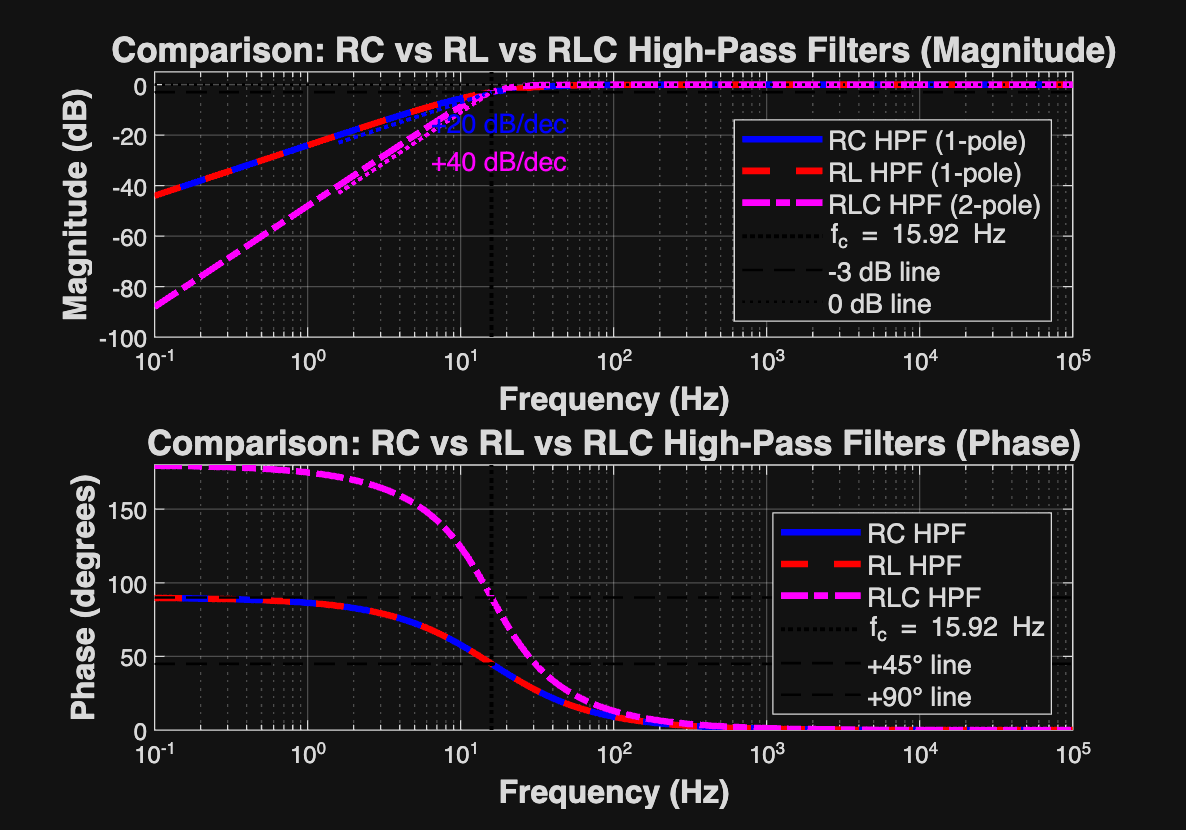

% Compute frequency response for RLC high-pass filter
[mag_rlc, phase_rlc] = bode(H_rlc_hp, w);
mag_rlc = squeeze(mag_rlc);
phase_rlc = squeeze(phase_rlc);
mag_dB_rlc = 20 * log10(mag_rlc);

% Compare all three high-pass filters
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_dB_rl, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_dB_rlc, 'm-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-100, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
semilogx([f(1), f(end)], [0, 0], 'k:', 'LineWidth', 1);

% Add roll-off annotations
f_decade_low = fc_rc / 10;
semilogx([f_decade_low, fc_rc], [-23, -3], 'b:', 'LineWidth', 1.5);
semilogx([f_decade_low, fc_rc], [-43, -3], 'm:', 'LineWidth', 1.5);
text(fc_rc/2.5, -15, '+20 dB/dec', 'FontSize', 10, 'Color', 'b');
text(fc_rc/2.5, -30, '+40 dB/dec', 'FontSize', 10, 'Color', 'm');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
% Continuing from section 13 (the ylabel line)...

ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL vs RLC High-Pass Filters (Magnitude)', ...
    'FontSize', 13, 'FontWeight', 'bold');
legend('RC HPF (1-pole)', 'RL HPF (1-pole)', 'RLC HPF (2-pole)', ...
    sprintf('f_c = %.2f Hz', fc_rc), '-3 dB line', '0 dB line', ...
    'Location', 'southeast', 'FontSize', 10);
ylim([-100, 5]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_rl, 'r--', 'LineWidth', 2.5);
semilogx(f, phase_rlc, 'm-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [0, 180], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [45, 45], 'k--', 'LineWidth', 1);
semilogx([f(1), f(end)], [90, 90], 'k--', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Comparison: RC vs RL vs RLC High-Pass Filters (Phase)', ...
    'FontSize', 13, 'FontWeight', 'bold');
legend('RC HPF', 'RL HPF', 'RLC HPF', sprintf('f_c = %.2f Hz', fc_rc), ...
    '+45° line', '+90° line', 'Location', 'southeast', 'FontSize', 10);
ylim([0, 180]);
xlim([f(1), f(end)]);

## 14. Filter Response Characteristics: Butterworth, Chebyshev, Bessel

Three Main Response Types (from Floyd's Chapter 15-2):

1. Butterworth Response: - Maximally flat passband (no ripples) - Roll-off: -20n dB/decade (n = filter order) - Phase response: Non-linear - Best for: Applications requiring flat amplitude response

2. Chebyshev Response: - Ripples in passband (faster roll-off than Butterworth) - Roll-off: Steeper than -20n dB/decade - Phase response: Less linear than Butterworth - Best for: Applications requiring sharp cutoff

3. Bessel Response: - Linear phase (constant group delay) - Roll-off: Slower than Butterworth - Phase response: Most linear - Best for: Pulse and time-domain applications

Damping Factor (ζ) and Q Factor:

ζ = 1/√2 ≈ 0.707 → Butterworth (critically damped) ζ < 0.707 → Chebyshev (underdamped, peaking) ζ > 0.707 → Bessel (overdamped)

## 15. Implementing Different Response Characteristics

Design RLC high-pass filters with different response characteristics

f0_comp = fc_rc;  % Same natural frequency for all

% Butterworth (ζ = 0.707, Q = 0.707)
zeta_butter = 1/sqrt(2);
Q_butter = 1/(2*zeta_butter);

% Chebyshev (ζ = 0.5, Q = 1.0) - 1dB ripple
zeta_cheby = 0.5;
Q_cheby = 1/(2*zeta_cheby);

% Bessel (ζ = 0.866, Q = 0.577)
zeta_bessel = 0.866;
Q_bessel = 1/(2*zeta_bessel);

% Component values for each type
C_comp = 1e-6;
L_comp = 1 / ((2*pi*f0_comp)^2 * C_comp);

R_butter = 2 * zeta_butter * sqrt(L_comp / C_comp);
R_cheby = 2 * zeta_cheby * sqrt(L_comp / C_comp);
R_bessel = 2 * zeta_bessel * sqrt(L_comp / C_comp);

% Create transfer functions
w0_comp = 2 * pi * f0_comp;

H_butter = s^2 / (s^2 + 2*zeta_butter*w0_comp*s + w0_comp^2);
H_cheby = s^2 / (s^2 + 2*zeta_cheby*w0_comp*s + w0_comp^2);
H_bessel = s^2 / (s^2 + 2*zeta_bessel*w0_comp*s + w0_comp^2);

fprintf('BUTTERWORTH HIGH-PASS FILTER:\n');

BUTTERWORTH HIGH-PASS FILTER:


fprintf('R = %.2f Ω, L = %.2f H, C = %.2f μF\n', R_butter, L_comp, C_comp/1e-6);

R = 14142.14 Ω, L = 100.00 H, C = 1.00 μF


fprintf('ζ = %.3f, Q = %.3f\n\n', zeta_butter, Q_butter);

ζ = 0.707, Q = 0.707




fprintf('CHEBYSHEV HIGH-PASS FILTER:\n');

CHEBYSHEV HIGH-PASS FILTER:


fprintf('R = %.2f Ω, L = %.2f H, C = %.2f μF\n', R_cheby, L_comp, C_comp/1e-6);

R = 10000.00 Ω, L = 100.00 H, C = 1.00 μF


fprintf('ζ = %.3f, Q = %.3f\n\n', zeta_cheby, Q_cheby);

ζ = 0.500, Q = 1.000




fprintf('BESSEL HIGH-PASS FILTER:\n');

BESSEL HIGH-PASS FILTER:


fprintf('R = %.2f Ω, L = %.2f H, C = %.2f μF\n', R_bessel, L_comp, C_comp/1e-6);

R = 17320.00 Ω, L = 100.00 H, C = 1.00 μF


fprintf('ζ = %.3f, Q = %.3f\n\n', zeta_bessel, Q_bessel);

ζ = 0.866, Q = 0.577



## 16. Frequency Response Comparison - Butterworth vs Chebyshev vs Bessel

Compute frequency responses

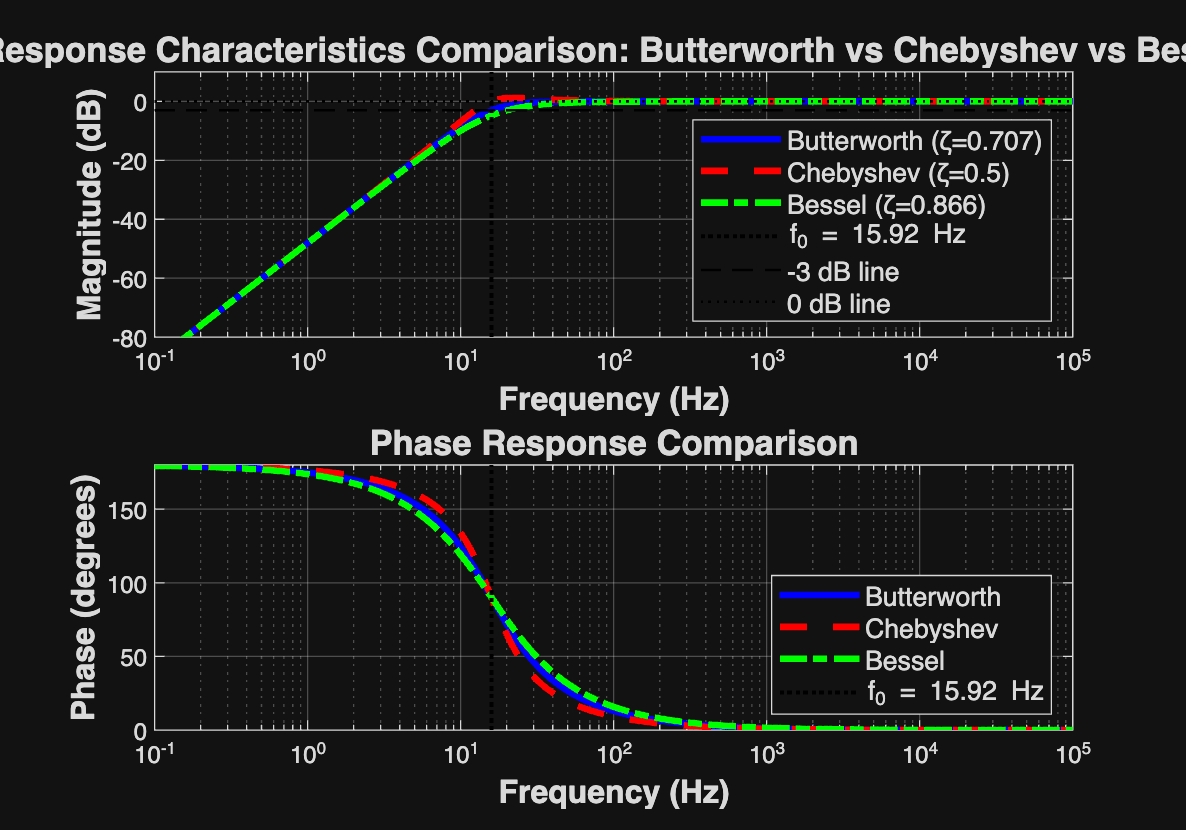

[mag_butter, phase_butter] = bode(H_butter, w);
mag_butter = squeeze(mag_butter);
phase_butter = squeeze(phase_butter);
mag_dB_butter = 20 * log10(mag_butter);

[mag_cheby, phase_cheby] = bode(H_cheby, w);
mag_cheby = squeeze(mag_cheby);
phase_cheby = squeeze(phase_cheby);
mag_dB_cheby = 20 * log10(mag_cheby);

[mag_bessel, phase_bessel] = bode(H_bessel, w);
mag_bessel = squeeze(mag_bessel);
phase_bessel = squeeze(phase_bessel);
mag_dB_bessel = 20 * log10(mag_bessel);

% Plot comparison
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_butter, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, mag_dB_cheby, 'r--', 'LineWidth', 2.5);
semilogx(f, mag_dB_bessel, 'g-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-80, 10], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);
semilogx([f(1), f(end)], [0, 0], 'k:', 'LineWidth', 1);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Response Characteristics Comparison: Butterworth vs Chebyshev vs Bessel', ...
    'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth (ζ=0.707)', 'Chebyshev (ζ=0.5)', 'Bessel (ζ=0.866)', ...
    sprintf('f_0 = %.2f Hz', f0_comp), '-3 dB line', '0 dB line', ...
    'Location', 'southeast', 'FontSize', 10);
ylim([-80, 10]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_butter, 'b-', 'LineWidth', 2.5);
hold on;
semilogx(f, phase_cheby, 'r--', 'LineWidth', 2.5);
semilogx(f, phase_bessel, 'g-.', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [0, 180], 'k:', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Phase Response Comparison', 'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth', 'Chebyshev', 'Bessel', ...
    sprintf('f_0 = %.2f Hz', f0_comp), 'Location', 'southeast', 'FontSize', 10);
ylim([0, 180]);
xlim([f(1), f(end)]);

## 17. Time-Domain Comparison - Step Response

Compare step responses of different characteristics

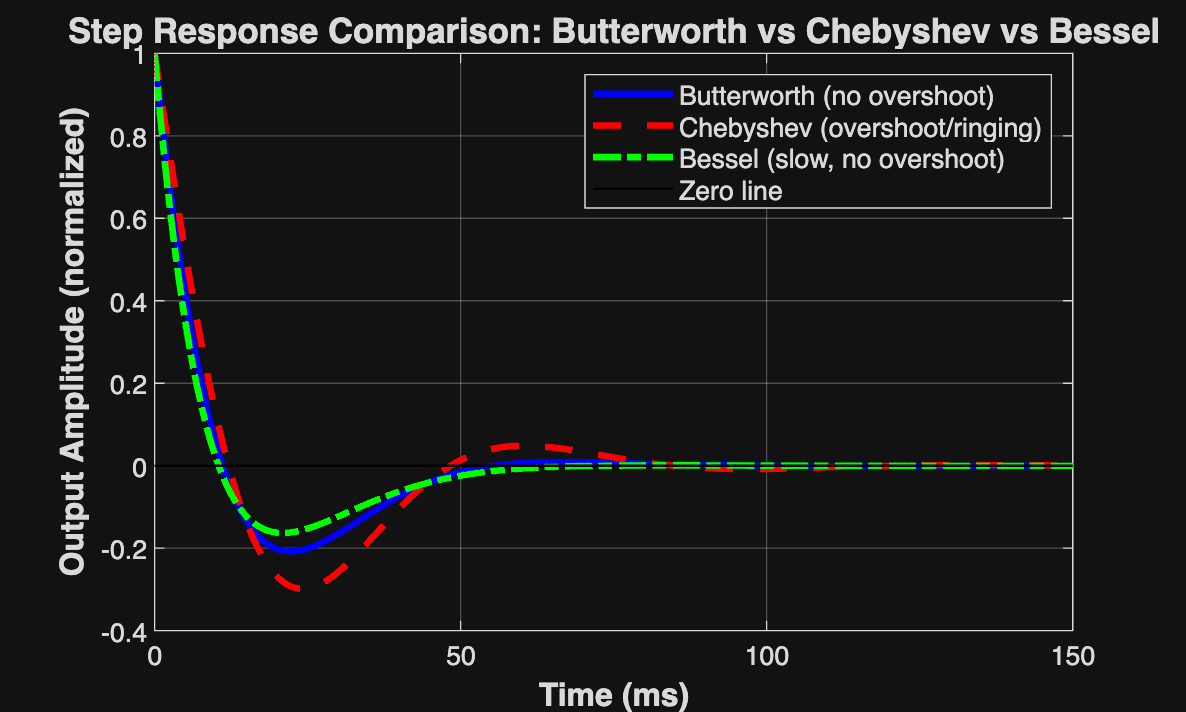

t_comp = linspace(0, 15*tau_rc, 2000);

[y_butter, t_butter] = step(H_butter, t_comp);
[y_cheby, t_cheby] = step(H_cheby, t_comp);
[y_bessel, t_bessel] = step(H_bessel, t_comp);

figure('Position', [100, 100, 1000, 600]);
plot(t_butter*1e3, y_butter, 'b-', 'LineWidth', 2.5);
hold on;
plot(t_cheby*1e3, y_cheby, 'r--', 'LineWidth', 2.5);
plot(t_bessel*1e3, y_bessel, 'g-.', 'LineWidth', 2.5);
plot([0, max(t_comp)*1e3], [0, 0], 'k-', 'LineWidth', 1);
hold off;
grid on;
xlabel('Time (ms)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Output Amplitude (normalized)', 'FontSize', 12, 'FontWeight', 'bold');
title('Step Response Comparison: Butterworth vs Chebyshev vs Bessel', ...
    'FontSize', 13, 'FontWeight', 'bold');
legend('Butterworth (no overshoot)', 'Chebyshev (overshoot/ringing)', ...
    'Bessel (slow, no overshoot)', 'Zero line', 'Location', 'northeast', 'FontSize', 10);
xlim([0, 15*tau_rc*1e3]);

## Step Response Analysis

Key Observations:

Butterworth Response: * Moderate transient behavior * Some overshoot possible * Good compromise between frequency and time domain

Chebyshev Response: * Significant overshoot and ringing * Fastest initial response * Best frequency selectivity but worst time-domain behavior * Not suitable for pulse applications

Bessel Response: * Minimal overshoot (most linear phase) * Slowest rise time * Best for preserving pulse shape * Ideal for time-domain applications

## 18. Cascaded High-Pass Filters - Higher Order Filters

Cascading filters increases order and steepness of roll-off Third-order: Cascade 2nd-order + 1st-order Fourth-order: Cascade two 2nd-order filters

% Design for Butterworth response (Table 15-1 from Floyd)
% Third-order Butterworth damping factors:
% Stage 1 (2-pole): ζ1 = 1.0
% Stage 2 (1-pole): Single pole (no damping factor needed)

% Fourth-order Butterworth damping factors:
% Stage 1 (2-pole): ζ1 = 0.924 (DF = 1.848)
% Stage 2 (2-pole): ζ2 = 0.383 (DF = 0.765)

% Create 3rd-order filter (2-pole + 1-pole)
zeta_3rd_stage1 = 1.0;
H_3rd_stage1 = s^2 / (s^2 + 2*zeta_3rd_stage1*wc_rc*s + wc_rc^2);
H_3rd_stage2 = (s*R_rc*C_rc) / (1 + s*R_rc*C_rc);
H_3rd_order = H_3rd_stage1 * H_3rd_stage2;

% Create 4th-order filter (2-pole + 2-pole)
zeta_4th_stage1 = 0.924;  % DF = 1.848
zeta_4th_stage2 = 0.383;  % DF = 0.765
H_4th_stage1 = s^2 / (s^2 + 2*zeta_4th_stage1*wc_rc*s + wc_rc^2);
H_4th_stage2 = s^2 / (s^2 + 2*zeta_4th_stage2*wc_rc*s + wc_rc^2);
H_4th_order = H_4th_stage1 * H_4th_stage2;

fprintf('CASCADED FILTER PARAMETERS:\n');

CASCADED FILTER PARAMETERS:


fprintf('=============================\n');

fprintf('3rd-order (2-pole + 1-pole):\n');

3rd-order (2-pole + 1-pole):


fprintf('  Stage 1 damping factor: ζ = %.3f\n', zeta_3rd_stage1);

  Stage 1 damping factor: ζ = 1.000


fprintf('  Roll-off rate: -60 dB/decade\n\n');

  Roll-off rate: -60 dB/decade




fprintf('4th-order (2-pole + 2-pole):\n');

4th-order (2-pole + 2-pole):


fprintf('  Stage 1 damping factor: ζ = %.3f\n', zeta_4th_stage1);

  Stage 1 damping factor: ζ = 0.924


fprintf('  Stage 2 damping factor: ζ = %.3f\n', zeta_4th_stage2);

  Stage 2 damping factor: ζ = 0.383


fprintf('  Roll-off rate: -80 dB/decade\n\n');

  Roll-off rate: -80 dB/decade



## 19. Frequency Response - Cascaded Filters

Compute frequency responses

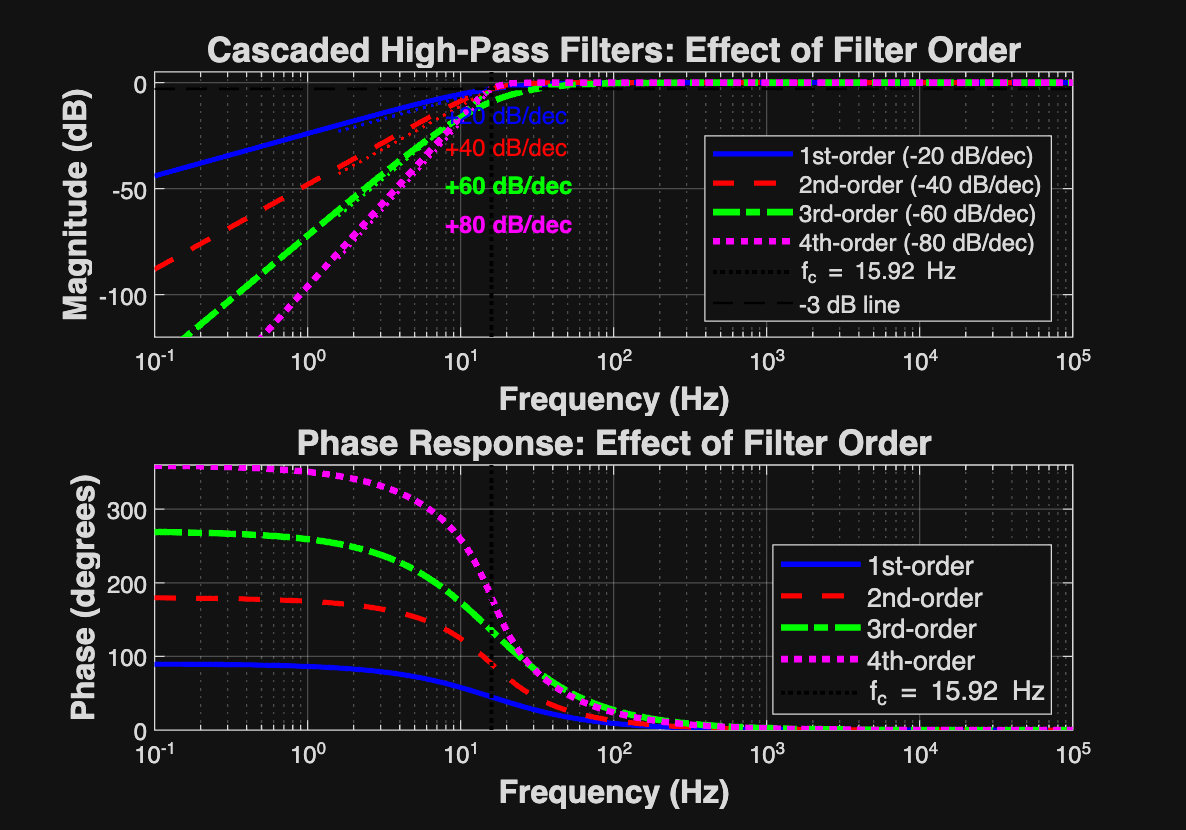

[mag_3rd, phase_3rd] = bode(H_3rd_order, w);
mag_3rd = squeeze(mag_3rd);
phase_3rd = squeeze(phase_3rd);
mag_dB_3rd = 20 * log10(mag_3rd);

[mag_4th, phase_4th] = bode(H_4th_order, w);
mag_4th = squeeze(mag_4th);
phase_4th = squeeze(phase_4th);
mag_dB_4th = 20 * log10(mag_4th);

% Compare all filter orders
figure('Position', [100, 100, 1000, 700]);

% Magnitude comparison
subplot(2, 1, 1);
semilogx(f, mag_dB_rc, 'b-', 'LineWidth', 2);
hold on;
semilogx(f, mag_dB_rlc, 'r--', 'LineWidth', 2);
semilogx(f, mag_dB_3rd, 'g-.', 'LineWidth', 2.5);
semilogx(f, mag_dB_4th, 'm:', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [-120, 5], 'k:', 'LineWidth', 1.5);
semilogx([f(1), f(end)], [-3, -3], 'k--', 'LineWidth', 1);

% Add roll-off annotations
f_decade = fc_rc / 10;
semilogx([f_decade, fc_rc], [-23, -3], 'b:', 'LineWidth', 1.2);
semilogx([f_decade, fc_rc], [-43, -3], 'r:', 'LineWidth', 1.2);
semilogx([f_decade, fc_rc], [-63, -3], 'g:', 'LineWidth', 1.2);
semilogx([f_decade, fc_rc], [-83, -3], 'm:', 'LineWidth', 1.2);

text(fc_rc/2, -15, '+20 dB/dec', 'FontSize', 9, 'Color', 'b');
text(fc_rc/2, -30, '+40 dB/dec', 'FontSize', 9, 'Color', 'r');
text(fc_rc/2, -48, '+60 dB/dec', 'FontSize', 9, 'Color', 'g', 'FontWeight', 'bold');
text(fc_rc/2, -66, '+80 dB/dec', 'FontSize', 9, 'Color', 'm', 'FontWeight', 'bold');

hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Cascaded High-Pass Filters: Effect of Filter Order', ...
    'FontSize', 13, 'FontWeight', 'bold');
legend('1st-order (-20 dB/dec)', '2nd-order (-40 dB/dec)', ...
    '3rd-order (-60 dB/dec)', '4th-order (-80 dB/dec)', ...
    sprintf('f_c = %.2f Hz', fc_rc), '-3 dB line', ...
    'Location', 'southeast', 'FontSize', 9);
ylim([-120, 5]);
xlim([f(1), f(end)]);

% Phase comparison
subplot(2, 1, 2);
semilogx(f, phase_rc, 'b-', 'LineWidth', 2);
hold on;
semilogx(f, phase_rlc, 'r--', 'LineWidth', 2);
semilogx(f, phase_3rd, 'g-.', 'LineWidth', 2.5);
semilogx(f, phase_4th, 'm:', 'LineWidth', 2.5);
semilogx([fc_rc, fc_rc], [0, 360], 'k:', 'LineWidth', 1.5);
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Phase (degrees)', 'FontSize', 12, 'FontWeight', 'bold');
title('Phase Response: Effect of Filter Order', 'FontSize', 13, 'FontWeight', 'bold');
legend('1st-order', '2nd-order', '3rd-order', '4th-order', ...
    sprintf('f_c = %.2f Hz', fc_rc), 'Location', 'southeast', 'FontSize', 10);
ylim([0, 360]);
xlim([f(1), f(end)]);

## Cascading Effects Analysis

Key Observations from Floyd's Textbook:

Roll-off Rate Relationship: * 1st-order: -20 dB/decade below fc * 2nd-order: -40 dB/decade below fc * 3rd-order: -60 dB/decade below fc * 4th-order: -80 dB/decade below fc * nth-order: -20n dB/decade below fc

Cascading Benefits: * Sharper transition from stopband to passband * Better frequency selectivity * Greater attenuation of unwanted frequencies

Cascading Considerations: * Increased circuit complexity * Higher component count * Potential for greater phase distortion * Requires proper damping factor selection for each stage

## 20. Practical Audio Application - DC Blocking / AC Coupling

Design Example: Audio AC Coupling Circuit

Specification: Block DC and pass audio frequencies above 20 Hz Application: Preventing DC offset from reaching speakers

% Design parameters
f_audio_cutoff = 20;  % 20 Hz cutoff for audio
C_audio = 10e-6;      % 10 μF electrolytic capacitor (common value)

% Calculate required resistance
R_audio = 1 / (2 * pi * f_audio_cutoff * C_audio);

fprintf('AUDIO AC COUPLING DESIGN:\n');

AUDIO AC COUPLING DESIGN:


fprintf('==========================\n');

fprintf('Application: DC blocking for audio amplifier\n');

Application: DC blocking for audio amplifier


fprintf('Specification: Pass audio above 20 Hz, block DC\n\n');

Specification: Pass audio above 20 Hz, block DC



fprintf('Design values:\n');

Design values:


fprintf('  Capacitor C = %.1f μF\n', C_audio/1e-6);

  Capacitor C = 10.0 μF


fprintf('  Resistor R = %.2f Ω (use %.0f Ω standard value)\n', R_audio, round(R_audio, -2));

  Resistor R = 795.77 Ω (use 800 Ω standard value)


fprintf('  Actual cutoff frequency = %.2f Hz\n', 1/(2*pi*round(R_audio,-2)*C_audio));

  Actual cutoff frequency = 19.89 Hz


fprintf('  Time constant τ = %.2f ms\n\n', round(R_audio,-2)*C_audio/1e-3);

  Time constant τ = 8.00 ms




% Create transfer function for audio filter
R_audio_std = round(R_audio, -2);  % Round to nearest 100Ω
fc_audio_actual = 1 / (2 * pi * R_audio_std * C_audio);
H_audio = (s*R_audio_std*C_audio) / (1 + s*R_audio_std*C_audio);

% Analyze audio frequency response
f_audio = logspace(0, 5, 2000);  % 1 Hz to 100 kHz
w_audio = 2 * pi * f_audio;
[mag_audio, phase_audio] = bode(H_audio, w_audio);
mag_audio = squeeze(mag_audio);
mag_dB_audio = 20 * log10(mag_audio);

## 21. Audio Filter Performance Visualization

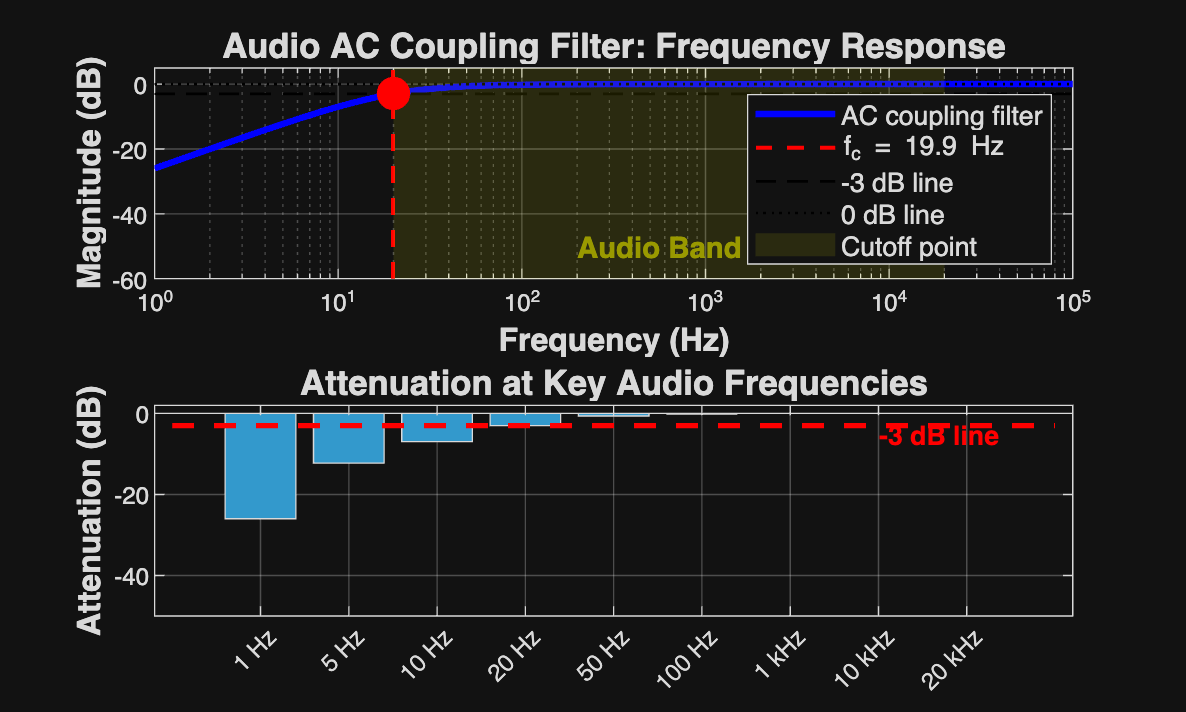

figure('Position', [100, 100, 1000, 600]);

% Magnitude response with audio band highlighted
subplot(2, 1, 1);
semilogx(f_audio, mag_dB_audio, 'b-', 'LineWidth', 2.5);
hold on;
semilogx([fc_audio_actual, fc_audio_actual], [-60, 5], 'r--', 'LineWidth', 1.5);
semilogx([f_audio(1), f_audio(end)], [-3, -3], 'k--', 'LineWidth', 1);
semilogx([f_audio(1), f_audio(end)], [0, 0], 'k:', 'LineWidth', 1);

% Highlight audio band (20 Hz - 20 kHz)
patch([20, 20000, 20000, 20], [-60, -60, 5, 5], 'y', ...
    'FaceAlpha', 0.1, 'EdgeColor', 'none');
text(200, -50, 'Audio Band', 'FontSize', 11, 'FontWeight', 'bold', 'Color', [0.6 0.6 0]);

plot(fc_audio_actual, -3, 'ro', 'MarkerSize', 12, 'MarkerFaceColor', 'r');
hold off;
grid on;
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Audio AC Coupling Filter: Frequency Response', 'FontSize', 13, 'FontWeight', 'bold');
legend('AC coupling filter', sprintf('f_c = %.1f Hz', fc_audio_actual), ...
    '-3 dB line', '0 dB line', 'Cutoff point', ...
    'Location', 'southeast', 'FontSize', 10);
ylim([-60, 5]);
xlim([f_audio(1), f_audio(end)]);

% Attenuation at key frequencies
subplot(2, 1, 2);
freq_points = [1, 5, 10, 20, 50, 100, 1000, 10000, 20000];
atten_points = zeros(size(freq_points));
for i = 1:length(freq_points)
    [~, idx] = min(abs(f_audio - freq_points(i)));
    atten_points(i) = mag_dB_audio(idx);
end

bar(atten_points, 'FaceColor', [0.2 0.6 0.8]);
set(gca, 'XTickLabel', {'1 Hz', '5 Hz', '10 Hz', '20 Hz', '50 Hz', ...
    '100 Hz', '1 kHz', '10 kHz', '20 kHz'});
xtickangle(45);
hold on;
plot([0, 10], [-3, -3], 'r--', 'LineWidth', 2);
text(8, -5, '-3 dB line', 'FontSize', 10, 'Color', 'r', 'FontWeight', 'bold');
hold off;
grid on;
ylabel('Attenuation (dB)', 'FontSize', 12, 'FontWeight', 'bold');
title('Attenuation at Key Audio Frequencies', 'FontSize', 13, 'FontWeight', 'bold');
ylim([-50, 2]);

## Audio Filter Performance Summary

fprintf('AUDIO FILTER PERFORMANCE:\n');

AUDIO FILTER PERFORMANCE:


fprintf('==========================\n');

fprintf('Attenuation at key frequencies:\n');

Attenuation at key frequencies:


for i = 1:length(freq_points)
    fprintf('  %6g Hz: %6.2f dB ', freq_points(i), atten_points(i));
    if atten_points(i) >= -0.5
        fprintf('(full pass)\n');
    elseif atten_points(i) >= -3
        fprintf('(passband)\n');
    else
        fprintf('(attenuated)\n');
    end
end

       1 Hz: -25.99 dB 

(attenuated)


       5 Hz: -12.28 dB 

(attenuated)


      10 Hz:  -6.94 dB 

(attenuated)


      20 Hz:  -2.99 dB 

(passband)


      50 Hz:  -0.64 dB 

(passband)


     100 Hz:  -0.17 dB 

(full pass)


    1000 Hz:  -0.00 dB 

(full pass)


   10000 Hz:  -0.00 dB 

(full pass)


   20000 Hz:  -0.00 dB 

(full pass)


fprintf('\n');

## 22. Comprehensive Performance Comparison Table

Create performance comparison table

FilterType = {'RC (1st-order)'; 'RL (1st-order)'; 'RLC (2nd-order)'; ...
    'Butterworth'; 'Chebyshev'; 'Bessel'; '3rd-order'; '4th-order'};

RollOff_dB_per_decade = [-20; -20; -40; -40; -40; -40; -60; -80];

Fc_Hz = [fc_rc; fc_rl; f0_rlc; f0_comp; f0_comp; f0_comp; fc_rc; fc_rc];

PhaseAt_Fc = [45; 45; 90; 90; 90; 90; 135; 180];

Applications = {'General AC coupling'; 'RF applications (rare)'; ...
    'Improved selectivity'; 'Maximally flat passband'; ...
    'Sharp cutoff, ripples OK'; 'Linear phase for pulses'; ...
    'High selectivity'; 'Very high selectivity'};

PerformanceTable = table(FilterType, RollOff_dB_per_decade, Fc_Hz, ...
    PhaseAt_Fc, Applications);

fprintf('HIGH-PASS FILTER COMPARISON TABLE:\n');

HIGH-PASS FILTER COMPARISON TABLE:


fprintf('====================================\n');

disp(PerformanceTable);

        FilterType         RollOff_dB_per_decade    Fc_Hz     PhaseAt_Fc            Applications        
    ___________________    _____________________    ______    __________    ____________________________

    {'RC (1st-order)' }             -20             15.915        45        {'General AC coupling'     }
    {'RL (1st-order)' }             -20             15.915        45        {'RF applications (rare)'  }
    {'RLC (2nd-order)'}             -40             15.915        90        {'Improved selectivity'    }
    {'Butterworth'    }             -40             15.915        90        {'Maximally flat passband' }
    {'Chebyshev'      }             -40             15.915        90        {'Sharp cutoff, ripples OK'}
    {'Bessel'         }             -40             15.915        90        {'Linear phase for

## 23. Key Design Equations Summary

Summary of Important Formulas from Floyd's Textbook

RC High-Pass Filter: fc = 1 / (2πRC) H(s) = sRC / (1 + sRC) = s / (s + 1/RC) τ = RC Phase at fc = +45° Roll-off = +20 dB/decade below fc

RL High-Pass Filter: fc = R / (2πL) H(s) = s / (s + R/L) τ = L/R Phase at fc = +45° Roll-off = +20 dB/decade below fc

RLC High-Pass Filter: f0 = 1 / (2π√(LC)) H(s) = s² / (s² + 2ζω₀s + ω₀²) ζ = (R/2)√(C/L) [damping ratio] Q = 1/(2ζ) = (1/R)√(L/C) [quality factor] Roll-off = +40 dB/decade below f0

Damping Ratio (ζ) Effects: ζ < 0.707: Underdamped (peaking, Chebyshev-like) ζ = 0.707: Critically damped (Butterworth, maximally flat) ζ > 0.707: Overdamped (Bessel-like, no peaking)

nth-Order Filter: Roll-off rate = 20n dB/decade below fc Phase shift at fc = n × 45°

fprintf('\n');
fprintf('========================================\n');

fprintf('   HIGH-PASS FILTER DESIGN SUMMARY     \n');

   HIGH-PASS FILTER DESIGN SUMMARY     


fprintf('========================================\n\n');


fprintf('Key Design Equations:\n');

Key Design Equations:


fprintf('---------------------\n');

---------------------


fprintf('RC High-Pass:  fc = 1/(2πRC)\n');

RC High-Pass:  fc = 1/(2πRC)


fprintf('RL High-Pass:  fc = R/(2πL)\n');

RL High-Pass:  fc = R/(2πL)


fprintf('RLC High-Pass: f0 = 1/(2π√(LC))\n\n');

RLC High-Pass: f0 = 1/(2π√(LC))

